# 第 6 章 	M文件和函数句柄

#### 	M文件：用MATLAB语言编写的程序，扩展名为 .m。

        M文件分为两类：脚本文件 (Script File) 和函数文件 (Function File)

#### 	比较简单的问题，特别是一次性的简单问题，

        从指令窗中直接输入指令进行计算是十分轻松的事。

        若所需的指令较多和所用指令结构较复杂，

        或当一组指令通过改变少量参数就可反复使用去解决不同问题时，

        直接在指令窗中输入指令的方法就显得烦琐和笨拙。

#### 	M文件可以保存多行命令并可以轻易地修改命令，可以重复使用。

#### 6.1	 MATLAB控制流

	MATLAB用于程序流控制的指令与其它语言相应指令的用法十分相似。

#### 6.1.1	if-else-end条件控 制

if-else-end指令为程序流提供了一种分支控制。

#### 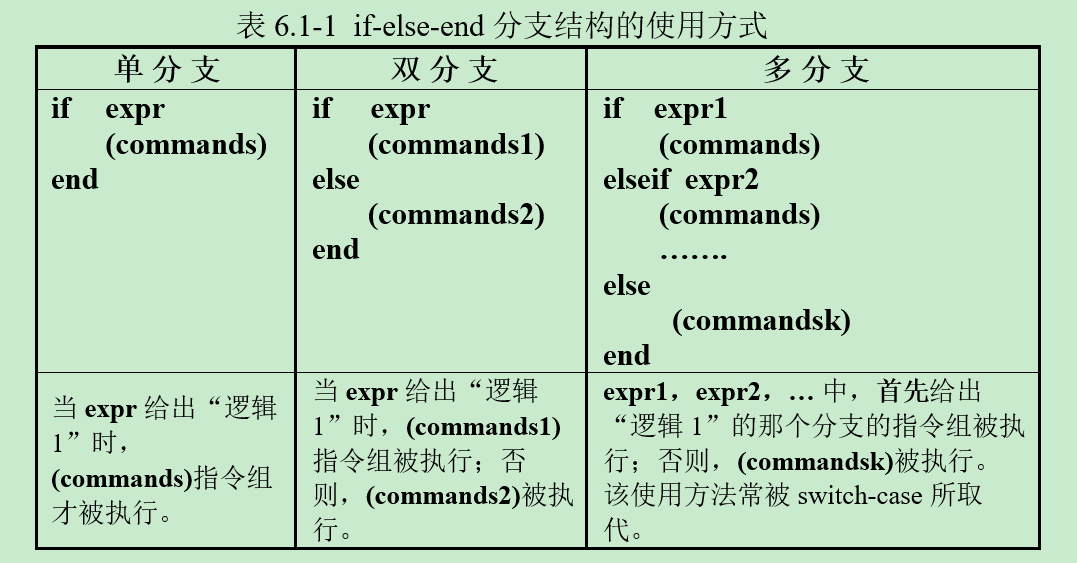

#### 〖说明〗

	expr通常是关系、逻辑运算构成的表达式。

        也可以是一般代数表达式，此时给出的任何非零值的作用等同于“逻辑1"。

	expr可以是逻辑数组，也可以是数值数组，

        仅当数组元素不包含任何零元素时expr控制的分支才被执行。

        expr为空数组被认为是假，expr控制的分支不被执行。

#### 6.1.2	  switch-case控制结构

#### 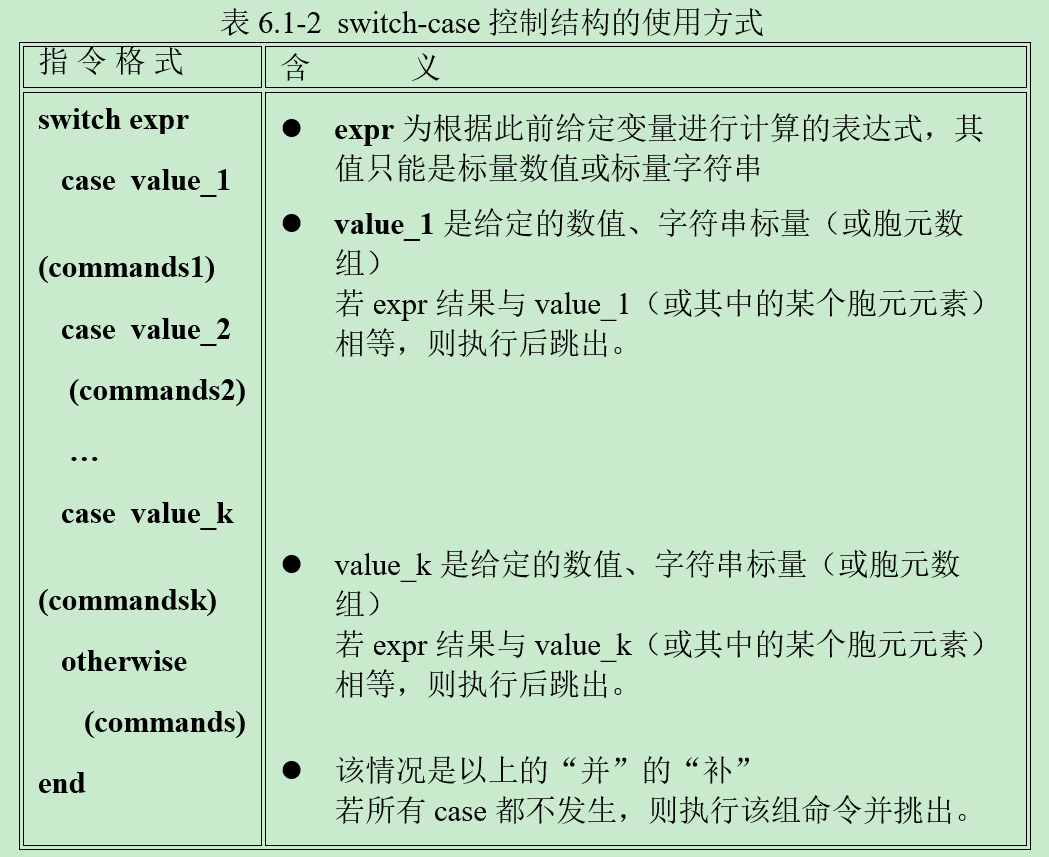

#### 〖说明〗

	Expr的值依次与case后的检测值比较，比较结果为真执行相应指令后跳出该结构。该结构只有一组命令会得到执行。

	expr的值只能是标量数值或字符串；case后的检测值可以是标量值、字符串或胞元数组；如果是胞元数组，expr的值与胞元数组中的每一个元素比较，结果有一个为真，比较结果为真。

#### 6.1.3	  for循环和while循环

#### 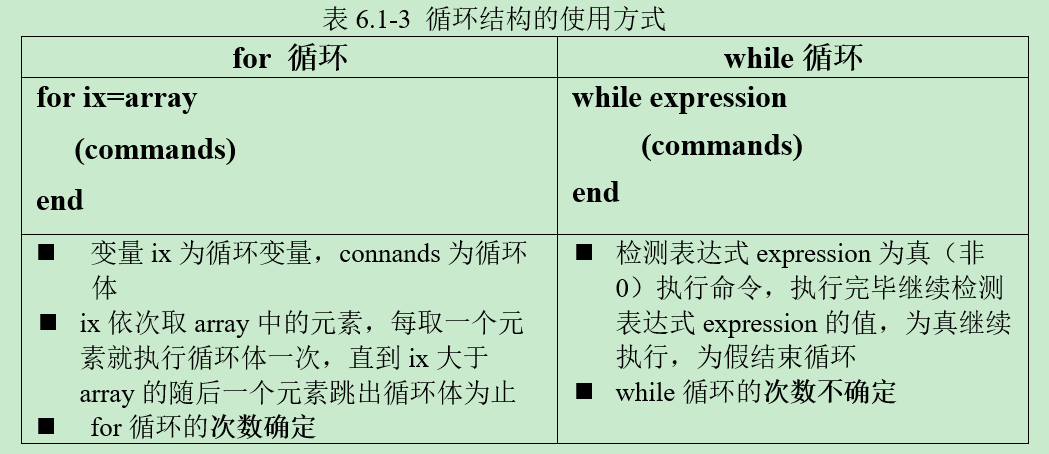

#### 6.1.4	  控制程序流的其它常用指令

#### 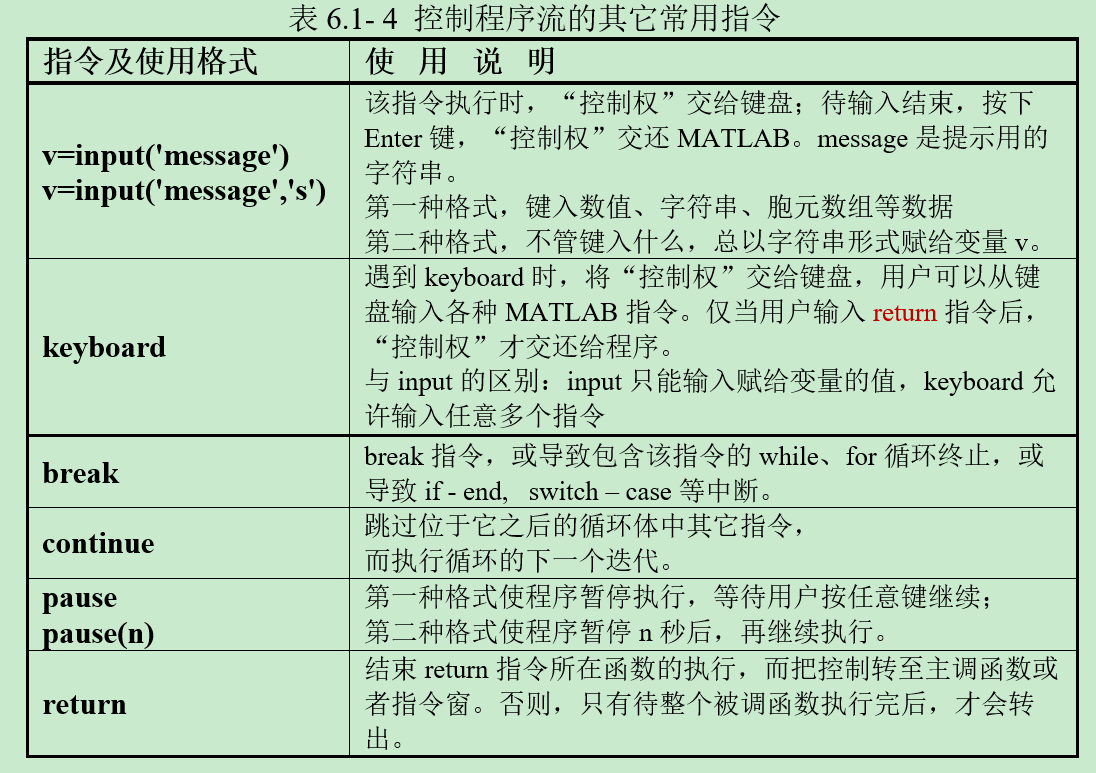

#### 【例 3.3-1】欧姆定律： r = u/i   ，其中r、u、i 分别是电阻（欧姆）、电压（伏特）、电流（安培）。

#### 验证实验：据电阻两端施加的电压，测量电阻中流过的电流，然后据测得的电压、电流计算平均电阻值。（测得的电压电流具体数据见下列程序）。

#### （1）非向量化程序

clear
vr=[0.89, 1.20, 3.09, 4.27, 3.62, 7.71, 8.99, 7.92, 9.70, 10.41];
ir=[0.028,0.040,0.100,0.145,0.118,0.258,0.299,0.257,0.308,0.345];						

% --------------------
L=length(vr);					
for k=1:L
	r(k)=vr(k)/ir(k);		
end	

% ---------------------------
sr=0;
for k=1:L
	sr=sr+r(k);				
	end
rm=sr/L						  

rm = 30.5247

rm =

   30.5247  

#### （2）向量化程序

clear
vr=[0.89, 1.20, 3.09, 4.27, 3.62, 7.71, 8.99, 7.92, 9.70, 10.41];
ir=[0.028,0.040,0.100,0.145,0.118,0.258,0.299,0.257,0.308,0.345];						
r=vr./ir						% 相同位置元素进行运算

r =    31.7857   30.0000   30.9000   29.4483   30.6780   29.8837   30.0669   30.8171   31.4935   30.1739


rm=mean(r)            % MATLAB现成的函数，查阅方法		 

rm = 30.5247

r =

  Columns 1 through 7

  31.7857  30.0000  30.9000  29.4483  30.6780  29.8837   30.0669

  Columns 8 through 10

  30.8171  31.4935  30.1739

rm =

   30.5247  

#### 【例6.1-4】编写计算

####                             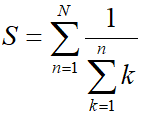 ，其中 ，  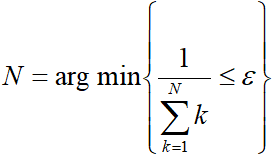  ,  是预先给定的控制精度。

#### （1）编写M函数文件exm060104.m

#### （2）把文件exm060104.m保存在处于MATLAB搜索路径上的文件夹中。

#### （3）运行以下指令(使用命令行窗口)，控制精度取0.0001。

%  [S,N]=exm060104(0.0001)  

    S =

        1.9859

    N =

       141  

#### 6.2	脚本文件和函数文件

#### 6.2.1	  M脚本文件

	脚本文件：包含多条MATLAB命令的综合体。是可以直接运行的文件。脚本文件没有输入、输出变量，产生的所有变量驻留在基本工作空间。与函数文件相比没有函数声明行。

	建立脚本文件：进入文件编辑器编辑：“新建脚本”/“新建”，在命令窗中运行edit ，在历史指令窗中选择多条指令点右键创建脚本文件。

	打开已有M文件：用工具栏上的“打开”图标，双击或打开当前目录的M文件，命令窗中运行指令：edit file;   edit file1 … fileN

	保存文件不必写出文件的扩展名，默认扩展名是“.m”。

	运行脚本文件：直接输入文件名，点击M编辑器中的“运行”图标 ，当前文件夹中选择文件运行。

	运行脚本时，只是从文件中读取一条条指令送到MATLAB中去执行。

#### 6.2.2	  M函数文件

	M函数文件是一个特殊的M文件，相当于对Matlab进行二次开发，通常在扩充Matlab函数库时使用

	与脚本文件不同，函数文件是不透明的，犹如一个“黑箱”，从外界只看到传给它的输入量和送出来的计算结果，

而内部运作从外界看是藏而不见的。

	函数文件的第一行是以funcion 引导的函数申明行，该行列出了函数与外界交换数据的全部“标称”输入和输出量

输入输出量的数目没有限制，可以完全没有，允许比标称数目少的输入输出量实现对函数的调用。

	函数文件运行时每个函数都分配有临时的函数工作空间

函数空间随具体的M函数文件的调用而产生，随调用结束而删除，所有中间变量都存放在函数工作空间中，并随函数空间的删除而删除；函数不使用基本工作空间，函数空间相对于基本空间是独立的、临时的；在MATALB运行期间，可以产生任意多个临时函数空间。

	函数文件调用脚本文件所产生的的变量都存在函数空间中而不是基本空间中。

#### 6.2.3	局部变量和全局变量

	局部（Local）变量

        存在于函数空间内部的中间变量，产生于该函数的运行过程中，

        其影响范围也仅限于该函数本身。

        正是由于这种空间、时间上的局部性，中间变量被称为局部变量。

	全局（Global）变量

        允许几个不同的函数空间以及基本工作空间共享同一个变量。

        全局变量必须通过global指令定义

        只有与全局变量联系的所有空间都被删除，全局变量才被删除。

        全局变量损害函数的封装性，不提倡使用。

#### 6.2.4	M函数文件的一般结构

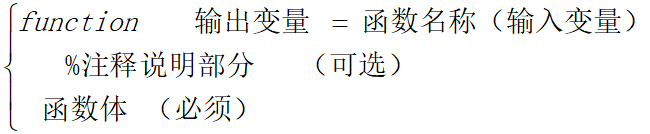

#### 函数申明行：以function开头的首行，包括函数名和输入/输出量名

####     函数文件名必须以字母开头，后面可是字母、下划线及数字的任意组合

####     函数文件名必须与函数名相同，两者不一致时以函数文件名为准

####     输入变量要用逗号隔开，输出变量多于1个时，要用[  ] 括起来。

####     输入/输出变量的个数可由两个保留变量nargin和nargout给出，

####     这是MATLAB提供的、只在函数文件中应用的函数

#### 	注释说明部分包括：

####     以%开头的申明行后的第一注释行（H1），包括函数名和函数功能描述

####     供look for关键词查询和help在线帮助使用。

####     以%开头的所有注释行构成在线帮助文本，可以采用英文或中文编写

####     它通常包括函数输入输出宗量的含义，调用格式说明等

####     编写修改记录：以%开头的编写、修改函数的作者、日期和版本记录，

####     用作软件档案管理，本行与在线帮助文本之间有一空行

#### 	函数体：为完成函数功能而编写的MATLAB命令

#### 	函数的调用格式：输出参数=函数名（输入参数）

#### 	与脚本文件相比，函数文件多一个函数申明行，其余相同

#### 	从运算角度看，只有函数申明行和函数体是必不可少的

【例6.3-1】编写一个M函数文件：根据指定半径求正多边形的面积和周长

（1）	编写M函数文件exm060201.m  

#### 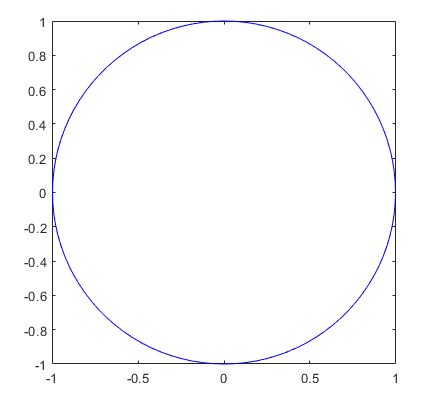

#### （2）把 exm060201.m文件保存在MATLAB的搜索路径上，

#### 然后在命令窗中运行以下命令。

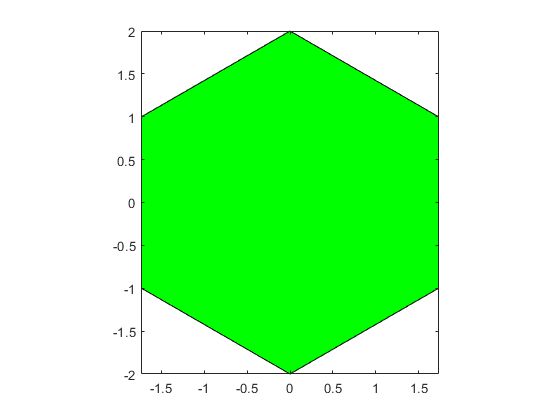

S = 10.3923

L = 12.0000

 [S,L]=exm060201(6,2,'-g')%计算外接半径为2的正六边形面积和周长并绘图

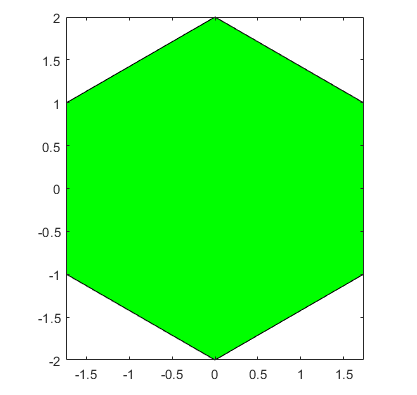

S =                      % 允许使用比标称数目少的输入/输出量

   10.3923

L =

   12.0000

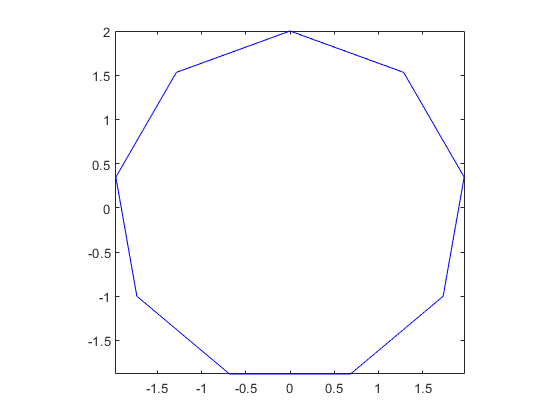

 exm060201(9,2)

#### 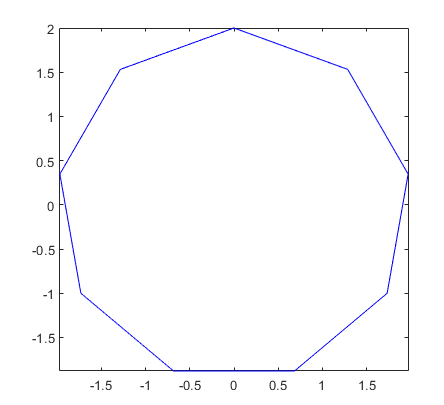

#### 6.3	MATLAB的函数类别

        在MATLAB 中，函数可分为：主函数、子函数、嵌套函数、私用函数和匿名函数等；

#### 6.3.1	主函数（Primary function）

        	一般与保存文件名同名的函数

        	在当前目录、收索路径上列出文件名的函数

        	在指令窗或其它函数中可直接调用的函数

        	在M文件中由第一个function引出的函数

        	用help可以获得帮助信息

#### 6.3.2	  子函数（Subfunction）

        	子函数不独立存在，只能寄生在主函数中

                子函数可以出现在子函数体内任何位置，其位置先后与调用次序无关

                一个M文件可以有多个子函数，但只能有一个主函数。

        	在函数文件中，由非第一个function 引出的函数

        	子函数只能被其所在的主函数和其它同居的子函数调用。

                任何指令通过名字对函数调用时，子函数的优先级仅次于内装函数

        	只要存在子函数句柄，无论在什么地方都可以直接调用子函数

        	同一文件的主函数和子函数的工作空间是彼此独立的

                各函数之间的信息可通过输入输出宗量或全局变量传递

        	用help指令可获取子函数信息

#### 6.3.3	匿名函数（Anonymous function）

        	匿名函数是MATLAB 7.0版提出的一种全新的函数描述形式

                可以让用户编写简单的函数而不需要创建M文件

        	匿名函数不以文件形式驻留在文件夹上；它的生成方式最简捷，

                可在指令窗或任何函数体内通过指令直接生成。

        	匿名函数的作用主要是实现在Matlab中自己定义函数，

                从而扩大函数的使用功能

        	匿名函数可以直接使用workspace中的变量，不必申明，

                非常适合嵌入到M文件中

#### 	创建和调用匿名函数：

        在指令窗或任何M文件中创建格式

                        FH=@(arglist)expr

                匿名函数的调用格式

                        FH(arglist)                                            直接调用

                        feval(FH,arglist)                                   间接调用

#### 〖说明〗

        FH是匿名函数句柄，

        arglist是输入量列表，

        创建和调用匿名函数句柄时的输入量arglist次序必须相同

        expr是由输入量构成的函数表达式

#### 6.4	函数句柄

    	函数句柄（Function handle）是MATLAB的一种数据类型

        包含了函数的路径、函数名、类型以及可能存在的重载方法

    	引入函数句柄是为了使feval及借助于它的泛函指令工作更可靠；

    	使“函数调用”像“变量调用”一样方便灵活：

        比如在一个目录创建了一个函数的句柄，当转到其他目录时，

        可以通过函数句柄直接调用上一个目录的函数，不需复制这个函数文件

        因为创建的函数句柄中已经包含了路径信息；

    	提高函数调用速度，特别在反复调用情况下更显效：

        MATLAB对函数的调用每次都是要搜索所有的路径，

        从set path中可以看到，路径是非常的多的，使用函数句柄，会提高速度

    	提高软件重用性，函数句柄的使用使得函数也可以成为输入变量，

        并且能很方便的调用，提高函数的可用性和独立性

        扩大子函数和私用函数的可调用范围；

        迅速获得同名重载函数的位置、类型信息。

    	函数句柄实际上提供了一种间接调用函数的方法。

#### 6.4.1	函数句柄的创建和观察

    	函数句柄并不伴随函数文件的创建和调用而自动形成，必须专门定义

    	定义函数句柄时不应包括路径信息和扩展名

    	被创建句柄的函数必须处在“当前视野内”

        当前视野：在当前目录下，help/lookfor/which等能发挥正常作用的范围

    	一般用的匿名函数实际上就是一种函数句柄

        对Matlab提供的各种M文件函数和内部函数也都可以创建函数句柄，

        从而可以对这些函数实现间接调用

    	函数句柄的生成方法有两种：利用@符号和利用转换函数str2func

        创建已命名函数的句柄：

        FH=@functionName

        FH=str2func(functionName)

        创建匿名函数的句柄：

                FH=@(arglist)expr

             FH=str2func('@(arglist)expr')

#### 6.4.2	函数句柄的基本用法

       假设原函数FunName的调用函数为

     [argout1,argout2,…,argoutn]=FunName(argin1,argin2,…,arginn)

        通过句柄调用函数的格式为：

       [argout1,argout2,…,argoutn]=Hfun(argin1,argin2,…,arginn)            直接调用格

       [argout1,argout2,…,argoutn]=feval(Hfun,argin1,argin2,…,arginn)   间接调用格式

####     〖说明〗

    	只要句柄被有效创建，句柄函数总能被有效执行

        不管FunName函数文件是否在当前收索路径上，不管它是否在当前视野，

        不管它是否是子函数或私用函数

    	句柄是MATLAB的标准数据类型之一，

        因此可以像MATLAB其他数据类型一样进行操作

    	函数句柄（function handle）是一种能够提供函数间接调用的matlab value。

        可以通过传递句柄来调用各种其他功能，

        也可以将句柄存储到数据结构中备用（例如Handle Graphic 回调）

    	在FunName存在重载函数时，借助句柄的计算总能被执行

        它会根据计算数据类型从重载函数中选择相应的函数文件执行

#### 【例题】为MATLAB的magic函数创建句柄，并观察其内涵。

#### （1）创建句柄

 hm=@magic      %对现有函数设置句柄；magic(n)

hm = 包含以下值的 function_handle :
    @magic


    hm = 

        @magic  

#### （2）类型判别

class(hm)

ans = 'function_handle'

isa(hm, 'function_handle')  

ans = logical
   1


    ans =

    function_handle

    ans =

         1  

#### （3）借助指令function观察内涵

% CC=functions(hm)           %function(Hfun)显示句柄函数信息

    CC = 

        function: 'magic'

            type: 'simple'

            file: 'C:\MATLAB R2010a\toolbox\matlab\elmat\magic.m'  

#### （4）句柄的调用方法之一

% M1=hm(4)  

    M1 =

        16     2     3    13

         5    11    10     8

         9     7     6    12

         4    14    15     1  

#### （5）句柄的调用方法之二

% M2=feval(hm,4)  

    M2 =

        16     2     3    13

         5    11    10     8

         9     7     6    12

         4    14    15     1  

#### 【例6.4-2】体验视野概念，检验文件是否存在于当前视野中；创建函数句柄，体验句柄不依赖视野而正确运作的能力。

#### （1）把 exm060201.m所在文件夹设置为当前文件夹并在当前目录中查看该文件；运行下述指令

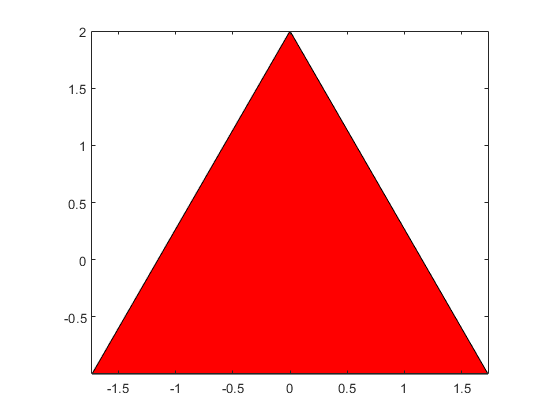

S = 5.1962

L = 10.3923

[S,L]=exm060201(3,2,'-r')	% 

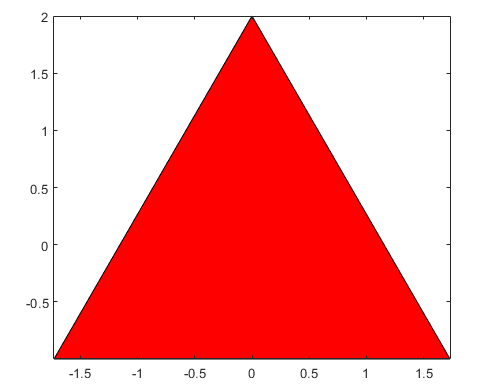

               图 6.4-1  直接调用函数exm060201所画的红色等边三角形

S =

        5.1962

    L =

       10.3923

#### 2）创建函数句柄

Hexm=@exm060201,		% 

Hexm = 包含以下值的 function_handle :
    @exm060201


    Hexm = 

        @exm060201  

#### （3）改变当前文件夹设置从而改变视野，观察文件exm060201.m。运行下述指令表明文件不在当前视野。

which('exm060201')  

C:\Users\ZhouJun\AppData\Local\Temp\Editor\LiveEditorEvaluationHelperE553433228.mlx (exm060201)  % Local function of LiveEditorEvaluationHelperE553433228


#### 'exm060201' not found.  

#### （5）新视野中调用函数文件失败

S = 5.1962

L = 10.3923

[S,L]=exm060201(3,2,'-r')  

    ??? Undefined command/function 'exm060201'.  

#### （6）新视野中，利用函数句柄仍可正常调用

S = 5.1962

L = 10.3923

[S,L]=Hexm(3,2,'-r')		%  

  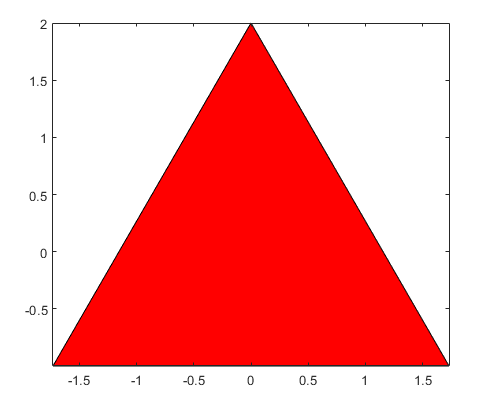

                图 6.4-2  在新视野中里用函数句柄Hexm所画的红色等边三角形

  S =

        5.1962

    L =

       10.3923

#### 【例6.4-3】创建句柄时，文件exm060201.m不在当前视野内，所创句柄是无效句柄

#### （1）清除所有变量

clear  

#### （2）创建不在视野中的文件exm060201.m的句柄

Hexm_2=@exm060201  

Hexm_2 = 包含以下值的 function_handle :
    @exm060201


    Hexm_2 = 

        @exm060201  

#### （3）下述指令无法判别句柄是否有效

class(Hexm_2)

ans = 'function_handle'

isa(Hexm_2,'function_handle')  

ans = logical
   1


    ans =

    function_handle

    ans =

         1  

#### （4）调用时无效

S = 5.1962

L = 10.3923

[S,L]=Hexm_2(3,2,'-r')  

    ??? Undefined command/function 'exm060201'.  

function [S,N]=exm060104(epsilon)
% [S,N]=exm060104(epsilon)
% 			Calculate the sum of a special series S=1+1/(1+2)+…+1/(1+2+…+N)
% S			Sum of a special series
% N     		The minimum among all numbers to have 1/sum(1:N)<epsilon
% epsilon  	Given accuracy
 
k=0;
s=0;
d=inf;
S=0;
while d>epsilon
    k=k+1;
    s=s+k;              
    d=1/s;  
    S=S+d;
end
N=k;
end
function [S,L]=exm060201(N,R,str)   %函数声明行，必不可少，脚本文件没有
% exm060201.m    The area and perimeter of a regular polygon         H1行 
% 	N 	The number of sides     H1行及其之后的所有注释行构成整个在线帮助文本区
%                                                  包含输入输出量含义和调用格式等
% 	R 		                           The circum radius
% 	str 		 		              A line specification to determine line type/color
% 	S 				              The area of the regular polygon
% 	L 				              The perimeter of the regular polygon
% exm060201      			用蓝实线画半径为 1 的圆
% exm060201(N)   			用蓝实线画外接半径为 1 的正 N 边形
% exm060201(N,R)  		用蓝实线画外接半径为 R 的正 N 边形
% exm060201(N,R,str)       用 str 指定的线画外接半径为 R 的正 N 边形
% S=exm060201(...)            给出多边形面积 S ,并画相应正多边形填色图
% [S,L]=exm060201(...)      给出多边形面积 S 和周长L,并画相应正多边形填色图

%  Zhang Zhiyong 修改于 2017-3-6
%  编写和修改记录，用于软件档案管理。与在线帮助文本区相隔一个空行

switch nargin                %  函数体，必不可少。为清晰起见，与前面的注释相隔一个空行
    case 0
        N=100;R=1;str='-b';          %  正100边形 ，近似为圆
    case 1
        R=1;str='-b';
    case 2
        str='-b';
    case 3
        ;					     %不进行任何变量操作，直接跳出switch-case控制结构
    otherwise
        error('输入量太多。');       % error(msg) 引发错误并显示错误消息
end;
t=0:2*pi/N:2*pi;
x=R*sin(t);y=R*cos(t); 
if nargout==0
   plot(x,y,str);
elseif nargout>2
   error('输出量太多。');        
else
   S=N*R*R*sin(2*pi/N)/2;	              % 多边形面积
   L=2*N*R*sin(pi/N);		              %  多边形周长
   fill(x,y,str)                                        %  填色
end
axis image                                           %  使图形边界抵达坐标轴范围
set(gcf,'Color','white')	       		   %  把图形窗背景色设置为白
box on
shg     
end